**완전 상미분방정식인지 확인하는 방법:**

- 미분방정식이 $M(x, y) \, dx + N(x, y) \, dy = 0$의 형태로 주어졌을 때, $M(x,y)$와 $N(x,y)$를 각각 $x$와 $y$에 대해 편미분합니다.

- 완전 상미분방정식의 조건은 $\frac{\partial M}{\partial y} = \frac{\partial N}{\partial x}$�이므로, 이 조건을 만족하는지 확인합니다.

% MATLAB 코드: 완전 상미분방정식 확인

% 심볼릭 변수 정의
syms x y

% M(x, y)와 N(x, y) 정의
M = -y;
N = x;

% M을 y에 대해 편미분
dM_dy = diff(M, y);

% N을 x에 대해 편미분
dN_dx = diff(N, x);

% 편미분 비교
if simplify(dM_dy - dN_dx) == 0
    disp('이 방정식은 완전 상미분방정식입니다.');
else
    disp('이 방정식은 완전 상미분방정식이 아닙니다.');
end

이 방정식은 완전 상미분방정식이 아닙니다.


**문제1**

**MATLAB에서 적분인자 찾기**

**예제 미분방정식**

다음과 같은 미분방정식이 있다고 가정합니다:


$$M(x, y) \, dx + N(x, y) \, dy = 0$$


예를 들어:


$$(2xy + y^2) \, dx + (x^2 + 2xy) \, dy = 0$$


**MATLAB 코드를 통한 적분인자 찾기**

- **심볼릭 변수 정의**: 먼저$ x$와 $y$를 심볼릭 변수로 정의합니다.

- **적분인자를 찾는 과정**: $M$과 $N$을 정의하고, 적분인자를 찾는 데 필요한 편미분을 계산합니다.

- **조건식 설정**: 적분인자가$ x$나 $y$에만 의존하는 경우를 가정하여 조건식을 설정하고 풀이합니다.

% 심볼릭 변수 정의
syms x y mu(x) mu_y(y)

% 주어진 M(x, y)와 N(x, y)
M = -y;
N = x;

% 1. 적분인자가 x의 함수일 때
% 적분인자 mu(x)와 연관된 편미분 계산
dM_dy = diff(M, y);
dN_dx = diff(N, x);

% 적분인자 찾기
% d(mu*M)/dy - d(mu*N)/dx = 0 이 되는 mu(x)를 찾음
mu_eq_x = diff(mu(x) * M, y) - diff(mu(x) * N, x);

% mu'(x) 찾기
mu_prime_x = simplify(mu_eq_x / M);

% 적분인자 mu(x) 계산
mu_x_sol = dsolve(diff(mu(x), x) == mu_prime_x);

disp('적분인자 mu(x):');

적분인자 mu(x):


disp(mu_x_sol);

$$\frac{C_{1}}{{\left(x-y\right)}^{2}}$$


% 2. 적분인자가 y의 함수일 때
% d(mu*N)/dx - d(mu*M)/dy = 0 이 되는 mu(y)를 찾음
mu_eq_y = diff(mu_y(y) * N, x) - diff(mu_y(y) * M, y);

% mu'(y) 찾기
mu_prime_y = simplify(mu_eq_y / N);

% 적분인자 mu(y) 계산
mu_y_sol = dsolve(diff(mu_y(y), y) == mu_prime_y);

disp('적분인자 mu(y):');

적분인자 mu(y):


disp(mu_y_sol);

$$\frac{C_{1}}{{\left(x-y\right)}^{2}}$$

**코드 설명**

- **심볼릭 변수 정의**: `syms`를 사용하여 $x$와 $y$를 심볼릭 변수로 정의합니다.

- **적분인자 가정**: 적분인자를 $\mu(x)$또는 $\mu(y)$로 가정합니다.

- **편미분 계산**: 적분인자를 곱한 후 편미분을 계산하고, 이를 통해 미분방정식이 완전 상미분방정식이 되도록 하는 조건을 설정합니다.

- **적분인자 계산**: `dsolve`를 사용하여 미분방정식을 풀고, 적분인자를 계산합니다.

우리의 실습에서는 적분인자는 $\frac{1}{x^2 }$ 으로 사전에 주어졌었지만, matlab 계산결과 적분인자는 $\frac{C_1 }{{\left(x-y\right)}^2 }$ 으로 도출되었다. 완전 상미분을 증명하기 때문에 C1은 불필요하며 1로 가정하면되고, 적분인자는 여러개가 나올수 있기 때문에 혹시나 잘못계산한 것인지 오해하지 않아도 된다.

아래는 확인 코드이다.

% MATLAB 코드: 완전 상미분방정식 확인

% 심볼릭 변수 정의
syms x y

% M(x, y)와 N(x, y) 정의
M = -y/(x-y)^2;
N = x/(x-y)^2;

% M을 y에 대해 편미분
dM_dy = diff(M, y);

% N을 x에 대해 편미분
dN_dx = diff(N, x);

% 편미분 비교
if simplify(dM_dy - dN_dx) == 0
    disp('이 방정식은 완전 상미분방정식입니다.');
else
    disp('이 방정식은 완전 상미분방정식이 아닙니다.');
end

이 방정식은 완전 상미분방정식입니다.


다음은 $\textrm{xydx}+\left(x^2 +2y^2 \right)\textrm{dy}=0\;$ 에대한 적분인자를 구해보자

1. 완전 상미분 방정식인지 확인하기

% MATLAB 코드: 완전 상미분방정식 확인

% 심볼릭 변수 정의
syms x y

% M(x, y)와 N(x, y) 정의
M = x*y;
N = x^2 + 2*y^2;

% M을 y에 대해 편미분
dM_dy = diff(M, y);

% N을 x에 대해 편미분
dN_dx = diff(N, x);

% 편미분 비교
if simplify(dM_dy - dN_dx) == 0
    disp('이 방정식은 완전 상미분방정식입니다.');
else
    disp('이 방정식은 완전 상미분방정식이 아닙니다.');
end

이 방정식은 완전 상미분방정식이 아닙니다.


2. 적분인자 찾기

% 심볼릭 변수 정의
syms x y mu(x) mu_y(y)

% 주어진 M(x, y)와 N(x, y)
M = x*y;
N = x^2 + 2*y^2;

% 1. 적분인자가 x의 함수일 때
% 적분인자 mu(x)와 연관된 편미분 계산
dM_dy = diff(M, y);
dN_dx = diff(N, x);

% 적분인자 찾기
% d(mu*M)/dy - d(mu*N)/dx = 0 이 되는 mu(x)를 찾음
mu_eq_x = diff(mu(x) * M, y) - diff(mu(x) * N, x);

% mu'(x) 찾기
mu_prime_x = simplify(mu_eq_x / (M * diff(mu(x), x)));

try
    % 적분인자 mu(x) 계산
    mu_x_sol = dsolve(diff(mu(x), x) == mu_prime_x, mu(0) == 1);
    disp('적분인자 mu(x):');
    disp(mu_x_sol);
    
    % 적분인자를 곱한 후 새로운 M과 N
    M_new_x = mu_x_sol * M;
    N_new_x = mu_x_sol * N;
    
    % 편미분 계산
    dM_new_dy_x = diff(M_new_x, y);
    dN_new_dx_x = diff(N_new_x, x);

    % 완전 상미분방정식 확인
    is_exact_x = simplify(dM_new_dy_x - dN_new_dx_x);
    if is_exact_x == 0
        disp('mu(x)가 완전 상미분방정식을 만듭니다.');
    else
        disp('mu(x)가 완전 상미분방정식을 만들지 않습니다.');
    end
catch
    disp('mu(x)에 대한 기호 해를 구할 수 없습니다.');
end

적분인자 mu(x):


mu(x)가 완전 상미분방정식을 만들지 않습니다.



% 2. 적분인자가 y의 함수일 때
% d(mu*N)/dx - d(mu*M)/dy = 0 이 되는 mu(y)를 찾음
mu_eq_y = diff(mu_y(y) * N, x) - diff(mu_y(y) * M, y);

% mu'(y) 찾기
mu_prime_y = simplify(mu_eq_y / (N * diff(mu_y(y), y)));

try
    % 적분인자 mu(y) 계산
    mu_y_sol = dsolve(diff(mu_y(y), y) == mu_prime_y, mu_y(0) == 1);
    disp('적분인자 mu(y):');
    disp(mu_y_sol);
    
    % 적분인자를 곱한 후 새로운 M과 N
    M_new_y = mu_y_sol * M;
    N_new_y = mu_y_sol * N;

    % 편미분 계산
    dM_new_dy_y = diff(M_new_y, y);
    dN_new_dx_y = diff(N_new_y, x);

    % 완전 상미분방정식 확인
    is_exact_y = simplify(dM_new_dy_y - dN_new_dx_y);
    if is_exact_y == 0
        disp('mu(y)가 완전 상미분방정식을 만듭니다.');
    else
        disp('mu(y)가 완전 상미분방정식을 만들지 않습니다.');
    end
catch
    disp('mu(y)에 대한 기호 해를 구할 수 없습니다.');
end

적분인자 mu(y):


mu(y)가 완전 상미분방정식을 만들지 않습니다.


위의 코드처럼 x 혹은 y만의 함수로 가정하고 적분인자를 구하는 코드를 사용하였지만 적분인자를 찾는것에 실패하였습니다.

여러가지 원인이 있을 수 있지만 적분인자가 f(x,y) 로 이루어진 형태이기 때문일 수 있습니다.

아래는 해석적 방법을 사용하였습니다.

% 심볼릭 변수 정의
syms x y mu(x, y)

% 주어진 M(x, y)와 N(x, y)
M = x * y;
N = x^2 + 2 * y^2;

% 편미분 계산
dM_dy = diff(M, y);
dN_dx = diff(N, x);

% 미분방정식이 완전 상미분방정식인지 확인
is_exact_original = simplify(dM_dy - dN_dx);
disp('원래 방정식이 완전 상미분방정식인지 확인:');

원래 방정식이 완전 상미분방정식인지 확인:


disp(is_exact_original);

$$-x$$


if is_exact_original == 0
    disp('주어진 방정식은 이미 완전 상미분방정식입니다.');
else
    disp('주어진 방정식은 완전 상미분방정식이 아닙니다.');
    % 적분인자 mu(x, y) 찾기
    % d(mu*M)/dy - d(mu*N)/dx = 0 이 되는 mu(x, y) 찾음
    mu_eq = diff(mu * M, y) - diff(mu * N, x);

    % 편미분 방정식 풀기
    [mu_sol, cond] = solve(mu_eq == 0, mu);
    
    % 일반화된 적분인자 mu(x, y)
    disp('일반화된 적분인자 mu(x, y):');
    disp(mu_sol);
end

주어진 방정식은 완전 상미분방정식이 아닙니다.


일반화된 적분인자 mu(x, y):


해석적 방법을 사용하였지만 해를 구할 수 없었습니다. 

**오류의 원인**

1. 주어진 미분방정식이 너무 복잡하거나 특이한 형태로 적분인자를 갖고 있어서 심볼릭 툴이 이를 해석하지 못한 경우

2. 적분인자가 특정 함수 형태로 존재하지 않거나, 위의 제시된 조건하에서 해를 찾을 수 없는 경우

3. 적분인자가 일반화 된 형태로 복잡하게 나타날때 

따라서 수치적 접근방법을 사용하였습니다.  

수치적 접근 방법을 사용하기 위해서는 적분인자에 대한 개략적인 수식이 필요합니다. 하지만 해석적 방법에 의한 정보를 얻을 수 없기 때문에 위에서 사용하였던 mu(x), mu(y)를 사용하였습니다.

% 심볼릭 변수 정의
syms x y C1

% 주어진 M(x, y)와 N(x, y)
M = x * y;
N = x^2 + 2 * y^2;

% 주어진 복잡한 적분인자
mu = (C1 * exp(((sqrt(sym(7)) * atan((2 * sqrt(sym(7)) * x + sqrt(sym(7)) * y) / (7 * y))) / 7))) / sqrt(x^2 + x * y + 2 * y^2);

% 수치적으로 방정식이 완전한지 확인
% x, y 값의 범위를 설정합니다.
x_vals = linspace(-10, 10, 50);
y_vals = linspace(-10, 10, 50);

% 결과 저장용
is_exact_vals = zeros(length(x_vals), length(y_vals));

for i = 1:length(x_vals)
    for j = 1:length(y_vals)
        x_val = x_vals(i);
        y_val = y_vals(j);
        
        % 주어진 적분인자를 수치적으로 평가
        mu_val = double(subs(mu, {x, y, C1}, {x_val, y_val, 1})); % C1 = 1로 설정
        
        % 새로운 M과 N을 수치적으로 평가
        M_new_val = mu_val * double(subs(M, {x, y}, {x_val, y_val}));
        N_new_val = mu_val * double(subs(N, {x, y}, {x_val, y_val}));
        
        % 수치적 편미분 계산 (유한차분법 사용)
        dM_new_dy = (mu_val * double(subs(M, {x, y}, {x_val, y_val + 0.01})) - M_new_val) / 0.01;
        dN_new_dx = (mu_val * double(subs(N, {x, y}, {x_val + 0.01, y_val})) - N_new_val) / 0.01;
        
        % 방정식이 완전한지 확인
        is_exact_vals(i, j) = dM_new_dy - dN_new_dx;
    end
end

% 평균 차이 계산
mean_difference = mean(abs(is_exact_vals), 'all');

% 결과 출력
if mean_difference < 1e-5
    disp('주어진 적분인자가 완전 상미분방정식을 만듭니다.');
else
    disp('주어진 적분인자가 완전 상미분방정식을 만들지 않습니다.');
end

% mean_difference을 사용하여 적분인자의 정확성을 확인합니다.
disp('평균 차이:');
disp(mean_difference);

% 심볼릭 변수 정의
syms x y C1

% 주어진 M(x, y)와 N(x, y)
M = x * y;
N = x^2 + 2 * y^2;

% 주어진 복잡한 적분인자
mu = C1 * exp(((2 * sqrt(sym(7)) * atan(sqrt(sym(7))/7 + (4 * sqrt(sym(7)) * y)/(7 * x))) / 7));

% 수치적으로 방정식이 완전한지 확인
% x, y 값의 범위를 설정합니다.
x_vals = linspace(-10, 10, 50);
y_vals = linspace(-10, 10, 50);

% 결과 저장용
is_exact_vals = zeros(length(x_vals), length(y_vals));

for i = 1:length(x_vals)
    for j = 1:length(y_vals)
        x_val = x_vals(i);
        y_val = y_vals(j);
        
        % 주어진 적분인자를 수치적으로 평가
        mu_val = double(subs(mu, {x, y, C1}, {x_val, y_val, 1})); % C1 = 1로 설정
        
        % 새로운 M과 N을 수치적으로 평가
        M_new_val = mu_val * double(subs(M, {x, y}, {x_val, y_val}));
        N_new_val = mu_val * double(subs(N, {x, y}, {x_val, y_val}));
        
        % 수치적 편미분 계산 (유한차분법 사용)
        dM_new_dy = (mu_val * double(subs(M, {x, y}, {x_val, y_val + 0.01})) - M_new_val) / 0.01;
        dN_new_dx = (mu_val * double(subs(N, {x, y}, {x_val + 0.01, y_val})) - N_new_val) / 0.01;
        
        % 방정식이 완전한지 확인
        is_exact_vals(i, j) = dM_new_dy - dN_new_dx;
    end
end

% 평균 차이 계산
mean_difference = mean(abs(is_exact_vals), 'all');

% 결과 출력
if mean_difference < 1e-5
    disp('주어진 적분인자가 완전 상미분방정식을 만듭니다.');
else
    disp('주어진 적분인자가 완전 상미분방정식을 만들지 않습니다.');
end

% mean_difference을 사용하여 적분인자의 정확성을 확인합니다.
disp('평균 차이:');
disp(mean_difference);

위의 방법도 제대로 된 적분인자를 찾을 수 없었습니다. 

다시 확인한 결과, 맨 처음 시도 했었던 방법은 $\mu (x)$와 $\mu_y(y)$를 각각 심볼릭 함수로 정의하고, 미분 방정식을 세워서 `dsolve`로 기호 해를 찾으려고 했습니다 .

이번에는 `dsolve`를 사용하지 않고 $R_x$와 $R_y$를 직접적으로 적분하여 적분 인자를 구하는 코드로 바꾸었습니다.

심볼릭 함수 대신, 적분 인자 $\mu$를 지수 함수 형태로 바로 계산합니다.

function mu = findIntegratingFactorModified(P, Q, x, y)
    % 우선 x만의 함수로 가정하고 식의 구성 요소를 찾음
    R_x = simplify((diff(P, y) - diff(Q, x)) / Q);
    
    % R_x가 x만의 함수인지 확인
    if isAlways(diff(R_x, y) == 0)

R_x is not a function of x alone.
The integrating factor as a function of y is:


$$y$$

        % 적분 인자 구하기
        mu = exp(int(R_x, x));
        disp('The integrating factor as a function of x is:');
        disp(mu);
        return;
    else
        disp('R_x is not a function of x alone.');
    end
    
    % 만약 실패한다면 y만의 함수로 가정
    R_y = simplify((diff(Q, x) - diff(P, y)) / P);
    
    % R_y가 y만의 함수인지 확인
    if isAlways(diff(R_y, x) == 0)
        % 적분 인자 구하기
        mu = exp(int(R_y, y));
        disp('The integrating factor as a function of y is:');
        disp(mu);
        return;
    else
        disp('R_y is not a function of y alone.');
    end
    
    % 적분 인자를 찾지 못한 경우

The equation with the integrating factor is an exact differential equation.


    mu = []; % 빈 배열을 반환
    disp('No integrating factor found as a function of x or y alone.');
end

% 예제 입력
syms x y;
P = x*y;
Q = x^2 + 2*y^2;

% 적분 인자 찾기
mu = findIntegratingFactorModified(P, Q, x, y);

적분인자는 F = y 인것으로 나타났습니다.

적분인자를 수식에 대입하여 상미분방적식이 되는지 확인하였습니다.

syms x y;
% 주어진 M(x, y)과 N(x, y)
M = x*y;
N = x^2 + 2*y^2;

% 가정한 적분 인자
mu = y;

% 새로운 M과 N 정의
M_new = mu * M;
N_new = mu * N;

General Solution:


$$\frac{x^{2}\,y^{2}}{2}+\frac{y^{4}}{2}=C$$

% 정확 미분 방정식인지 확인
exactCheck = diff(M_new, y) == diff(N_new, x);

% 결과 출력
if simplify(exactCheck)
    disp('The equation with the integrating factor is an exact differential equation.');
else
    disp('The equation with the integrating factor is not an exact differential equation.');
end

일반해를 찾고 포텐셜 함수로 시각화를 진행하였다.

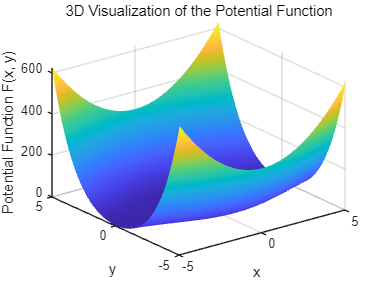

syms x y C;
% 주어진 M(x, y)와 N(x, y)
M = x*y;
N = x^2 + 2*y^2;

% 적분 인자 적용
mu = y;

M_new = mu * M;
N_new = mu * N;

% 일반해를 찾기 위한 포텐셜 함수 F(x, y) 찾기
% F의 x에 대한 편미분이 M_new, y에 대한 편미분이 N_new여야 함
% ∂F/∂x = M_new
F_x = int(M_new, x); % x에 대해 적분
F_y = int(N_new, y); % y에 대해 적분

% F_x와 F_y 사이에 겹치는 부분을 고려하여 일반해를 찾음
% F_y를 다시 F_x에 포함되지 않는 부분만 남김
F_potential = F_x + int(N_new - diff(F_x, y), y);

% 일반해: F(x, y) = C
general_solution = F_potential == C;

disp('General Solution:');
disp(general_solution);

% 3D 그래프로 포텐셜 함수 시각화
% x, y의 범위 설정
[x_mesh, y_mesh] = meshgrid(-5:0.1:5, -5:0.1:5);
% 포텐셜 함수 계산
F_potential_func = matlabFunction(F_potential);
F_values = F_potential_func(x_mesh, y_mesh);

% 3D 그래프 그리기
figure;
surf(x_mesh, y_mesh, F_values);
xlabel('x');
ylabel('y');
zlabel('Potential Function F(x, y)');
title('3D Visualization of the Potential Function');
shading interp;


The integrating factor is:


$${\mathrm{e}}^{2\,x}$$

The general solution is:


$$\frac{y^{2}\,{\mathrm{e}}^{2\,x}}{2}$$

**문제2**

$y^2 \, dx + y \, dy = 0$에 대한 적분 인자를 찾고 일반해를 구하였습니다.

syms x y;
% 미분 방정식 정의
P = y^2;
Q = y;

% 적분 인자 R 구하기
% R = (1/Q) * (diff(P, y) - diff(Q, x))
R = (1/Q) * (diff(P, y) - diff(Q, x));
R = simplify(R);

% 적분 인자가 x만의 함수인지 확인
if isAlways(diff(R, y) == 0)
    % 적분 인자 구하기
    integratingFactor = exp(int(R, x));
    disp('The integrating factor is:');
    disp(integratingFactor);
    
    % 새로운 P와 Q 정의
    P_new = simplify(integratingFactor * P);
    Q_new = simplify(integratingFactor * Q);

The equation with the integrating factor is an exact differential equation.


    
    % 일반해 구하기
    % 완전 미분 방정식 F(x, y) = C에서
    % F(x, y) = int(P_new, x) + int(Q_new, y) - int(dF/dy, y)
    F_x = int(P_new, x);
    dF_dy = diff(F_x, y);
    F_y = int(Q_new - dF_dy, y);
    
    % 완전 미분 방정식 일반해
    F = F_x + F_y;
    disp('The general solution is:');
    disp(F);
else
    disp('The integrating factor is not a function of x alone.');

The general solution F(x, y) is:


end

$$\frac{y^{2}\,{\mathrm{e}}^{2\,x}}{2}=C$$

적분인자 ${\mathrm{e}}^{2\,x}$ 이 맞는지 확인하였습니다.

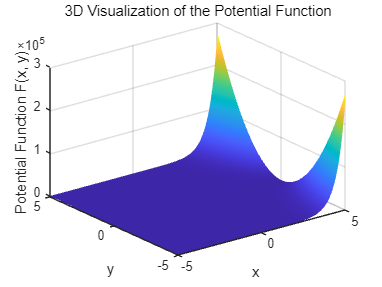

syms x y C;
% 주어진 미분 방정식 정의
P = y^2;
Q = y;

% 구해진 적분 인자
integratingFactor = exp(2*x);

% 새로운 P와 Q 정의 (적분 인자를 곱한 형태)
P_new = simplify(integratingFactor * P);
Q_new = simplify(integratingFactor * Q);

% 1. 완전 미분 방정식인지 확인

exactCheck = diff(P_new, y) == diff(Q_new, x);
if isAlways(exactCheck)
    disp('The equation with the integrating factor is an exact differential equation.');
else
    disp('The equation with the integrating factor is not an exact differential equation.');
end

% 2. 일반해 구하기
% 포텐셜 함수 F(x, y) 찾기
% ∂F/∂x = P_new
F_x = int(P_new, x); % x에 대해 적분
% ∂F/∂y = Q_new
F_y = int(Q_new - diff(F_x, y), y); % F_x에서 y에 대한 부분만 추가

% 포텐셜 함수 F(x, y)
F = simplify(F_x + F_y);

% 일반해: F(x, y) = C
generalSolution = F == C;
disp('The general solution F(x, y) is:');
disp(generalSolution);

% 3D 그래프로 포텐셜 함수 시각화
% x, y의 범위 설정
[x_mesh, y_mesh] = meshgrid(-5:0.1:5, -5:0.1:5);
% 포텐셜 함수 계산
F_potential_func = matlabFunction(F);
F_values = F_potential_func(x_mesh, y_mesh);

% 3D 그래프 그리기
figure;
surf(x_mesh, y_mesh, F_values);
xlabel('x');
ylabel('y');
zlabel('Potential Function F(x, y)');
title('3D Visualization of the Potential Function');
shading interp;


적분인자를 곱해서 확인한 결과 완전상미분 방정식 임을 확인하였습니다.

따라서 올바르게 구한것을 확인하였습니다.